# Getting the PSD from data through Welch estimator

## Introduction

In this tutorial you will learn how to estimate the PSD of a random process from a time series through the Welch estimator. The time series is assumed to be a realisation of a zero-mean random process. The PSD estimation is based on the sample spectrum. To obtain a smooth PSD estimation, the time series is divided into a number of overlapped segments. Then, the sample spectrum of the segments are obtained. Their average represents the estimated PSD. Additionally, a data window is applied to the segments as a means to calibrate the trade-off between resolution and leakage.

The dataset employed in this tutorial is '*database/case_01_Mann_1V*', which includes a synthetic time series of the longitudinal component of turbulent wind fluctuation (zero mean), according to the Mann's model, and the related true spectrum. This allows comparison between the estimated PSD and the true PSD. 

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

N_f         = 100;   % number of elements of the frequency vector.

N_seg       = 8;     % Number of segments in which the time series is divided.
                     % Leave empty [] for default value (see function
                     % 'fun_default_value').

overlap     = 0.5;   % fraction of segment that is overlapped. 0.5 is for 50%.
                     % Leave empty [] for default value (see function
                     % 'fun_default_value').

window_name = 'Hamming';    % Name of the window applied to the segments.
                            % For a list of window names, see function
                            % 'initialise_window'. 
                            % Leave empty [] for default value (see function
                            % 'fun_default_value').

%%% Plot parameters
font_size       = 14;
figure_position = [0 0 1000 400];
CC              = colororder;
color_estimated = CC(5,:);
color_true      = CC(4,:);
color_fmin      = CC(1,:);
color_ss        = 0.5*[1 1 1];

Load the dataset. It consists of two objects, one in the form of a `data` object, and one in the form of a `S` object. For details related to the fields of these objects, see functions `initialise_data` and `initialise_S`.

load case_01_Mann_1V.mat

Have a look at the time series considered. 

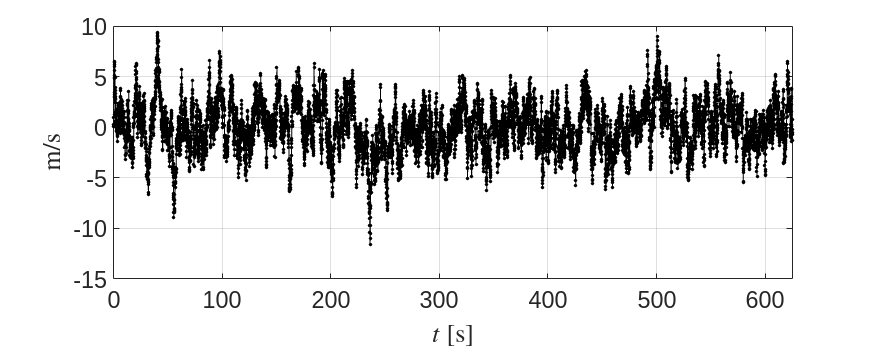

figure

x = data_Mann.x_values;
y = data_Mann.y_values;
plot(x,y,'.-k')

grid on
xlabel('$t$ [s]','Interpreter','latex')
ylabel('m/s','Interpreter','latex')
xlim([0 data_Mann.x_values(end)])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

Note the sampling time and the time span of the data. They are useful to define the maximum frequency, $f_{max}$, and the minimum frequency, $f_{min}$. The frequency vector to evaluate the sample spectrum, `f_vector`, will be defined within this frequency range. Log scale will be employed for convenience (see tutorial '*getting_S_from_data_through_sample_spectrum*' for details).

delta_t     = data_Mann.x_parameters.delta_x;   % seconds
t_sim       = delta_t*data_Mann.x_parameters.N; % seconds

f_max       = 1/(2*delta_t);
f_min       = 1/t_sim;

f_vector    = logspace(log10(f_min),log10(f_max),N_f);

Initialise an S object  with the fields required by function get_S_data`_Welch`. 

S0 = initialise_S('x_values', f_vector);

Initialise a `window` object with the fields required by function get_S_data`_Welch`.

window = initialise_window('name',window_name);

Compute the PSD of the data. Since the data is univariate, there is no need to specify the column with parameter `k_index` (see details in function get_S_data`_Welch`).

[S_Welch, S_seg] = get_S_data_Welch(data_Mann, S0, N_seg, overlap, window);

Plot the obtained PSD together with the true spectrum. Remark on the minimum frequency, $f_{min}$, higher that the value obtained above based on $t_{sim}$ (see first element of `f_vector`), because with Welch method the minimum frequency is based on the duration of the segments.

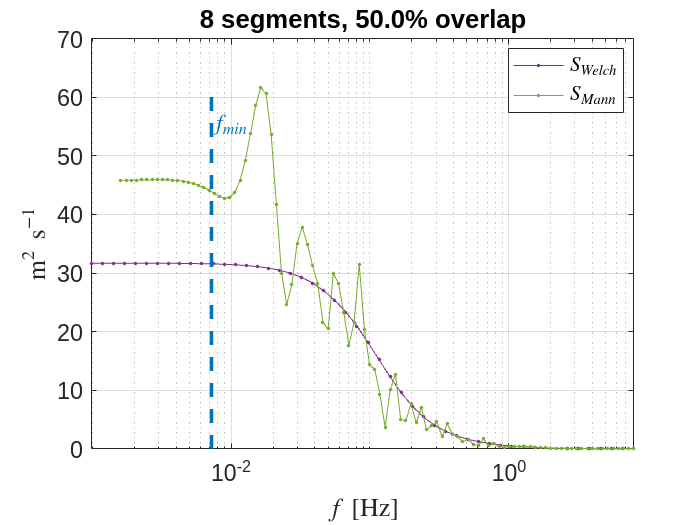

figure

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,y,'.-','color',color_true)

hold on

x = S_Welch.x_values;
y = S_Welch.y_values;
plot(x,y,'.-','color',color_estimated)

x_min = S_Welch.x_parameters.x_min;
y_max = max(y);
plot([x_min x_min],[0 y_max ],'--','color',color_fmin,'LineWidth',2)
text(1.05*x_min,0.9*y_max,'$f_{min}$',...
     'color',color_fmin,...
     'fontsize',font_size,...
     'Interpreter','latex')

grid on
legend({'$S_{Welch}$','$S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$ \, s$^{-1}$','Interpreter','latex')
title_string = sprintf('%d segments, %.1f%% overlap',N_seg,100*overlap);
title(title_string)

set(gca,'fontsize',font_size)
set(gca,'Xscale','log')

Note the extra output `S_seg`, which is an S object. It contains the sample spectra obtained for the segments in which the original time series was divided. The Welch estimation results from averaging these spectra estimations.

Plot the Welch estimation together with the sample spectra.

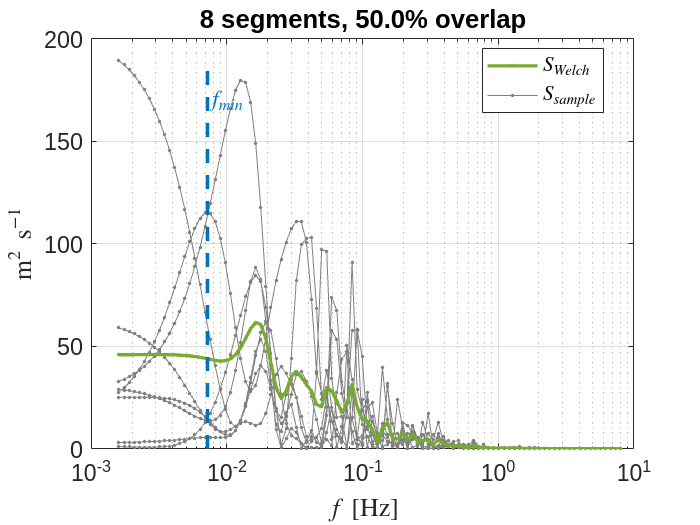

figure

x = S_seg.x_values;
y = S_seg.y_values;
h1 = plot(x,y,'.-','color',color_ss);

hold on

x = S_Welch.x_values;
y = S_Welch.y_values;
h2 = plot(x,y,'.-','color',color_estimated,'LineWidth',2);

x_min = S_Welch.x_parameters.x_min;
y_max = max(max(S_seg.y_values));
plot([x_min x_min],[0 y_max ],'--','color',color_fmin,'LineWidth',2)
text(1.05*x_min,0.9*y_max,'$f_{min}$',...
     'color',color_fmin,...
     'fontsize',font_size,...
     'Interpreter','latex')

grid on
legend([h2 h1(1)],{'$S_{Welch}$','$S_{sample}$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$ \, s$^{-1}$','Interpreter','latex')
title_string = sprintf('%d segments, %.1f%% overlap',N_seg,100*overlap);
title(title_string)

set(gca,'fontsize',font_size)
set(gca,'Xscale','log')

For the case of wind turbulence, two common representations are the product $f \cdot S$ in log-linear scales, and $S$ in log-log scales.

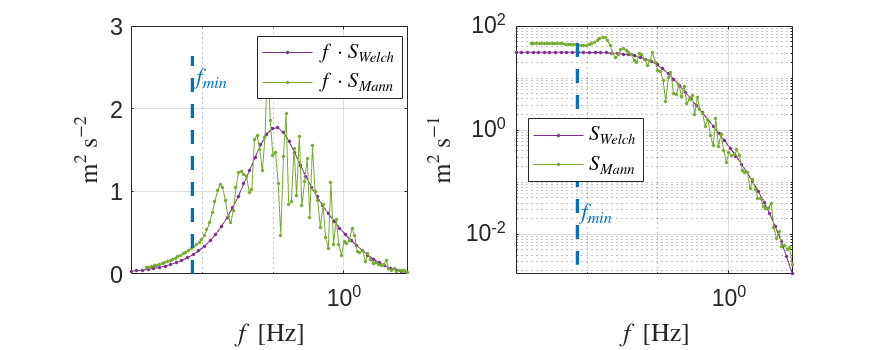

figure


subplot(1,2,1)

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,x.*y,'.-','color',color_true)

hold on

x = S_Welch.x_values;
y = S_Welch.y_values;
plot(x,x.*y,'.-','color',color_estimated)

y_max = max(x.*y);
plot([x_min x_min],[0 y_max ],'--','color',color_fmin,'LineWidth',2)
text(1.05*x_min,0.9*y_max,'$f_{min}$',...
     'color',color_fmin,...
     'fontsize',font_size,...
     'Interpreter','latex')

grid on
legend({'$f \cdot S_{Welch}$','$f \cdot S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$  s$^{-2}$','Interpreter','latex')
set(gca,'Xscale','log')
set(gca,'fontsize',font_size)


subplot(1,2,2)

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,y,'.-','color',color_true)

hold on

x = S_Welch.x_values;
y = S_Welch.y_values;
plot(x,y,'.-','color',color_estimated)

y_min = min(y);
y_max = max(y);
plot([x_min x_min],[y_min y_max ],'--','color',color_fmin,'LineWidth',2)
text(1.05*x_min,10*y_min,'$f_{min}$',...
     'color',color_fmin,...
     'fontsize',font_size,...
     'Interpreter','latex')

grid on
legend({'$S_{Welch}$','$S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$ s$^{-1}$','Interpreter','latex')

set(gca,'Xscale','log')
set(gca,'Yscale','log')
set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

## Remarks

- Note that the PSD is a continuous function of the frequency, and it can be evaluated at any frequency value. 

- However, the PSD estimated from a discrete time series is periodic for frequencies higher thant $f_{max} $. You can check it just by changing `f_vector` accordingly (and ploting the PSD in x-linear scale). 

- Also, the estimated spectrum for frequencies below $f_{min}$ is likely to be inaccurate because the time simulation of the data, `t_sim`, is not long enough to capture such small frequencies. An important issue of the Welch estimator is that the considered simulation time is that of the segment, which is, by definition, shorter than the original time series. This leads to an increase of the minimum frequency with the number of segments, reducing the range of frequencies where the PSD estimation could be reliable. Reducing the overlap has a similar effect on the minimum frequency.

- The Welch estimator performs reasonably well as compared with the sample spectrum, and actually is one of the most commonly employed PSD estimators. One of the reasons is the smoothing effect due to the averaging operation over the sample spectra computed for the segments. Actually, the number of segments and the overlap are key parameters of this estimator, and a trial-and-error procedure is usually necessary. You can check the different accuracy of the estimator for different values of parameters `N_seg` and `overlap`. Be aware also of the impact on $f_{min}$.

- The employed window applied to the segments also has an effect on the PSD estimator. You can check the impact of using different windows on the estimated PSD by changing the parameter `window_name`.